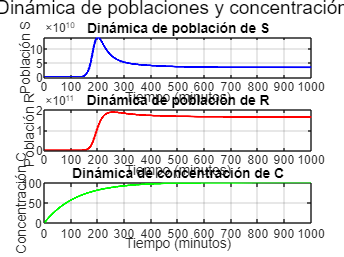

format long
% Parámetros iniciales
beta_S = 0.4; % tasa de crecimiento de S (poblacion/tiempo) (meses)
beta_R = 0.1; % tasa de crecimiento de R 
alfa_S = 0.0012; % eliminación de S
K = 10^12; % capacidad de carga de S y R (numero de poblaciones)
q = 0.3992; % fracción de S que adquieren resistencia
u_S = 0.2; % tasa de muerte natural de S 
u_R = 0.09; % tasa de muerte natural de R
u_C = 0.0083; % tasa de degradación de C
A = 0.8328; % dosis inicial de C (mg/minuto)

% Sistema de ecuaciones
dS = @(t, S, R, C) beta_S*S*(1-(S+R)/K) - alfa_S*C*S - u_S*S;
dR = @(t, S, R, C) beta_R*R*(1-(S+R)/K) + q*alfa_S*C*S - u_R*R;  
dC = @(t, C) A - u_C*C;

% Valores iniciales, experimento n°2
S0 = 1.2484;
R0 = 1.1;
C0 = 0.1204*u_C/alfa_S;

% Intervalo de tiempo (en minutos)
h = 0.1; % Paso de tiempo
t = 0:h:1000;

% Implementación de RK4
[S, R, C] = RK4(dS, dR, dC, S0, R0, C0, t, h);

% Gráficos separados para S, R y C
figure;


subplot(3, 1, 1);
plot(t, S, 'b', 'LineWidth', 1.5);
xlabel('Tiempo (minutos)');
ylabel('Población S');
title('Dinámica de población de S');
grid on;


subplot(3, 1, 2);
plot(t, R, 'r', 'LineWidth', 1.5);
xlabel('Tiempo (minutos)');
ylabel('Población R');
title('Dinámica de población de R');
grid on;


subplot(3, 1, 3);
plot(t, C, 'g', 'LineWidth', 1.5);
xlabel('Tiempo (minutos)');
ylabel('Concentración C');
title('Dinámica de concentración de C');
grid on;


% Ajuste del espacio entre subplots
sgtitle('Dinámica de poblaciones y concentración');



initial_conditions = [S0, R0, C0];

% Intervalo de tiempo (en minutos)
tspan = [0:h:1000];
% Método de Runge-Kutta de cuarto orden (RK4)
[tt, Y] = ode45(@(t, y) [dS(t, y(1), y(2), y(3));
                      dR(t, y(1), y(2), y(3));
                      dC(t, y(3))], tspan, initial_conditions);
% Extracción de resultados
Sexacta = Y(:, 1);
Rexacta = Y(:, 2);
Cexacta = Y(:, 3);
Saprox = S;
Raprox = R;
Caprox = C;
%Calculando el error relativo y relativo porcentual
%Para S
error_relS = abs(Sexacta - Saprox')./abs(Sexacta)

error_relS =                    0
   0.000000000025566
   0.000000002301912
   0.000000004351940
   0.000000003654262
   0.000000001502522
   0.000000000376065
   0.000000326542487
   0.000001130316872
   0.000002190550230


error_rel_porcentualS = abs(Sexacta - Saprox')./abs(Sexacta)*100

error_rel_porcentualS =                    0
   0.000000002556619
   0.000000230191236
   0.000000435193973
   0.000000365426240
   0.000000150252232
   0.000000037606541
   0.000032654248660
   0.000113031687159
   0.000219055023043


%Para R
error_relR = abs(Rexacta - Raprox')./abs(Rexacta)

error_relR = 1.0e-03 *

                   0
   0.000000000201042
   0.000000037918321
   0.000000042220745
   0.000000001924848
   0.000000021988363
   0.000000002973741
   0.000015178967174
   0.000052430952246
   0.000101028790364


error_rel_porcentualR = abs(Rexacta - Raprox')./abs(Rexacta)*100

error_rel_porcentualR =                    0
   0.000000000020104
   0.000000003791832
   0.000000004222074
   0.000000000192485
   0.000000002198836
   0.000000000297374
   0.000001517896717
   0.000005243095225
   0.000010102879036


%Para S
error_relC = abs(Cexacta - Caprox')./abs(Cexacta)

error_relC = 1.0e-05 *

                   0
   0.000000000036388
   0.000000003471508
   0.000000006104956
   0.000000004679351
   0.000000001587492
   0.000000000133856
   0.000000491339588
   0.000001659309837
   0.000003148021548


error_rel_porcentualC = abs(Cexacta - Caprox')./abs(Cexacta)*100

error_rel_porcentualC = 1.0e-03 *

                   0
   0.000000000036388
   0.000000003471508
   0.000000006104956
   0.000000004679351
   0.000000001587492
   0.000000000133856
   0.000000491339588
   0.000001659309837
   0.000003148021548



%Cantidad de casos que cumple error < 1%
[casesS, casesR, casesC] = countErrorsBelowThreshold(error_rel_porcentualS, error_rel_porcentualR, error_rel_porcentualC, 1);

fprintf('Número de casos en bacterias susceptibles donde los errores relativos porcentuales son menores al 1 por ciento: %d.\n', casesS);

Número de casos en bacterias susceptibles donde los errores relativos porcentuales son menores al 1 por ciento: 10001.


fprintf('Número de casos en bacterias resistentes donde los errores relativos porcentuales son menores al 1 por ciento: %d.\n', casesR);

Número de casos en bacterias resistentes donde los errores relativos porcentuales son menores al 1 por ciento: 10001.


fprintf('Número de casos en concentración de antibiótico donde los errores relativos porcentuales son menores al 1 por ciento: %d.\n', casesC);

Número de casos en concentración de antibiótico donde los errores relativos porcentuales son menores al 1 por ciento: 10001.


function [countS, countR, countC] = countErrorsBelowThreshold(error_rel_porcentualS, error_rel_porcentualR, error_rel_porcentualC, threshold)
    % Inicializar contadores
    countS = 0;
    countR = 0;
    countC = 0;

    % Contar casos para S
    for i = 1:length(error_rel_porcentualS)
        if error_rel_porcentualS(i) < threshold
            countS = countS + 1;
        end
    end

    % Contar casos para R
    for i = 1:length(error_rel_porcentualR)
        if error_rel_porcentualR(i) < threshold
            countR = countR + 1;
        end
    end

    % Contar casos para C
    for i = 1:length(error_rel_porcentualC)
        if error_rel_porcentualC(i) < threshold
            countC = countC + 1;
        end
    end
end


% Implementación de la función RK4
function [S, R, C] = RK4(dS, dR, dC, S0, R0, C0, t, h)
    num_steps = length(t);
    %Creamos un vector de ceros
    S = zeros(1, num_steps);
    R = zeros(1, num_steps);
    C = zeros(1, num_steps);
    
    %Rellenamos con las condiciones iniciales
    S(1) = S0;
    R(1) = R0;
    C(1) = C0;
    
    for i = 1:num_steps-1
        % Valores actuales
        Si = S(i);
        Ri = R(i);
        Ci = C(i);
        
        % k1
        k1_S = dS(t(i), Si, Ri, Ci);
        k1_R = dR(t(i), Si, Ri, Ci);
        k1_C = dC(t(i), Ci);
        
        % k2
        k2_S = dS(t(i) + h/2, Si + k1_S*(h/2), Ri + k1_R*(h/2), Ci + k1_C*(h/2));
        k2_R = dR(t(i) + h/2, Si + k1_S*(h/2), Ri + k1_R*(h/2), Ci + k1_C*(h/2));
        k2_C = dC(t(i) + h/2, Ci + k1_C*(h/2));
        
        % k3
        k3_S = dS(t(i) + h/2, Si + k2_S*(h/2), Ri + k2_R*(h/2), Ci + k2_C*(h/2));
        k3_R = dR(t(i) + h/2, Si + k2_S*(h/2), Ri + k2_R*(h/2), Ci + k2_C*(h/2));
        k3_C = dC(t(i) + h/2, Ci + k2_C*(h/2));
        
        % k4
        k4_S = dS(t(i) + h, Si + k3_S*h, Ri + k3_R*h, Ci + k3_C*h);
        k4_R = dR(t(i) + h, Si + k3_S*h, Ri + k3_R*h, Ci + k3_C*h);
        k4_C = dC(t(i) + h, Ci + k3_C*h);
        
        % Actualización de variables
        S(i+1) = Si + (h/6)*(k1_S + 2*k2_S + 2*k3_S + k4_S);
        R(i+1) = Ri + (h/6)*(k1_R + 2*k2_R + 2*k3_R + k4_R);
        C(i+1) = Ci + (h/6)*(k1_C + 2*k2_C + 2*k3_C + k4_C);
    end
end